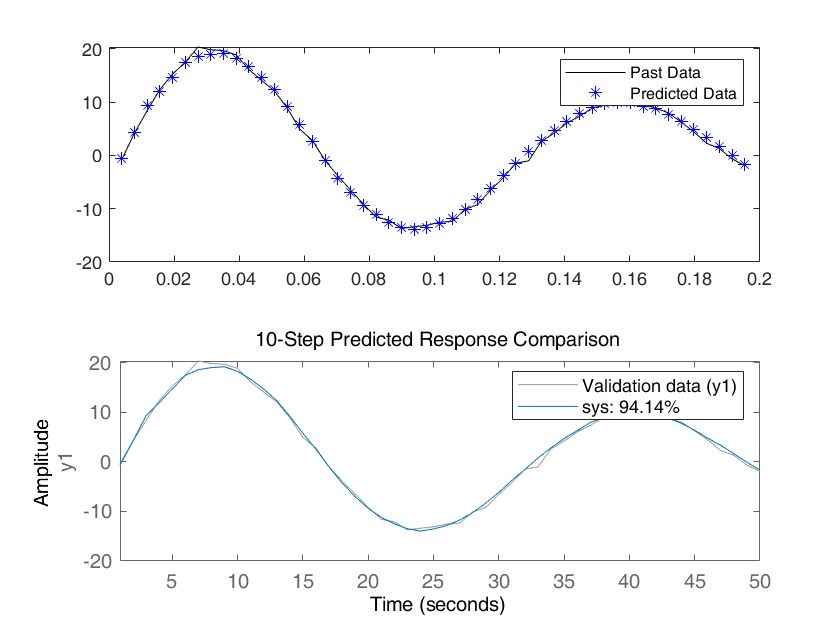

% 采用ARMA进行预测 2019年2月26日

close all
clear
clc

load iddata9 z9
past_data = z9.OutputData(1:50);
sys = armax(past_data,[4 3]);
yp = predict(sys,past_data,10);
t = z9.SamplingInstants;
t1 = t(1:50);
figure(1)
subplot(2,1,1)
plot(t1,past_data,'k',t1,yp,'*b')
legend('Past Data','Predicted Data')
subplot(2,1,2)
compare(past_data,sys,10);

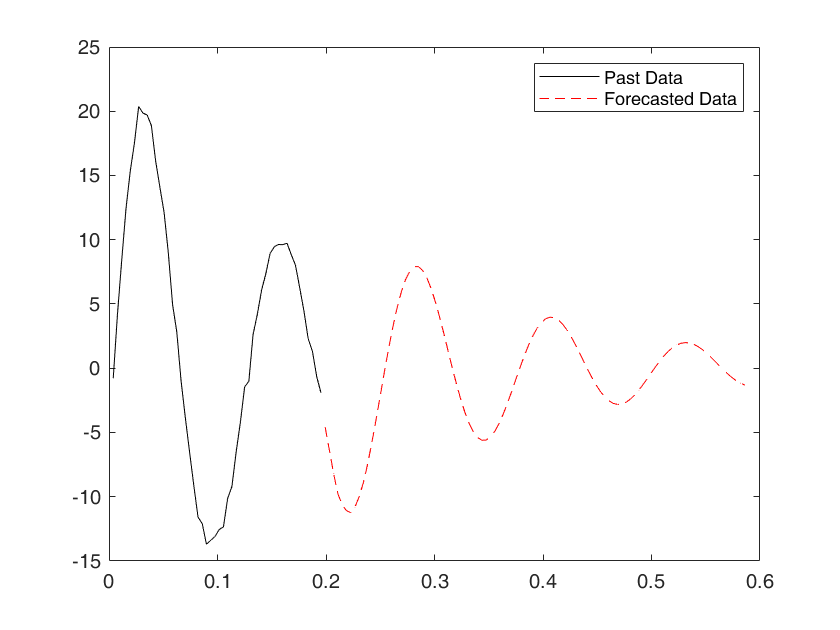

opt = forecastOptions('InitialCOndition','z');
H = 100;
yf = forecast(sys,past_data,H,opt);
t2 = t(51:150)';
figure(2)
plot(t1,past_data,'k',t2,yf,'--r')
legend('Past Data','Forecasted Data')

测试记录_190226

在使用forecast进行预测时，如果函数输入的pastdata数据类型为double型数组，则函数预测输出数据类型为double型数组；如果函数输入的pastdata数据类型为iddata，则函数预测输出数据类型为iddata。